# ** GRN Project 1**

Consider the simplified Guido-Collins system with an activator transcription factor and an inhibitor transcription factor. 

You may use the code `GuidoCollins_simplified01.m` Section 2.3

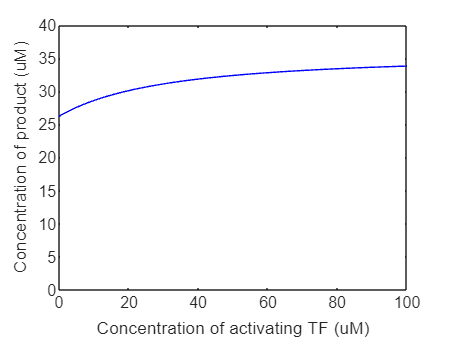

paramArray = 0:1:100;
g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    delta_m = 0.05;
    gamma_g = 0.02;
    delta_g = 0.01;
    
    gamma_g2 = 0.1;
    
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1
    
    I = 10; % EDIT FOR HW1
    C = paramArray(iParam); % ENDOGENOUS activatory transcription factor % EDIT FOR HW1
    
    M =@(C2,t) [-kon*(C+C2)-kon*I,  +koff*I,          koff     ,        0;
                +kon*I,             -koff*I-kon*(C+C2),             0,   +koff;
                +kon*(C+C2)      ,              0,   -koff-kon*I,   +koff;
                        0,          kon*(C+C2),         kon*I, -2*koff];
    
    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;
    
    f =@(p0,pr,pa,par,m,g,m2,C2) +gamma_m(p0,pr,pa,par)   - delta_m*m;
    g =@(p0,pr,pa,par,m,g,m2,C2) +gamma_g*m - delta_g*g;
    
    f2 =@(p0,pr,pa,par,m,g,m2,C2) + gamma_m(p0,pr,pa,par)   - delta_m*m2;
    g2 =@(p0,pr,pa,par,m,g,m2,C2) + gamma_g2*m2 - delta_g*C2;
    
    
    initialCondition = [1,0,0,0,0,0,0,0];
    
    dxdt = @(t,x)[M(x(8),t)*[x(1);x(2);x(3);x(4)];
        f(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
        g(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
        f2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
        g2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end

figure(17); clf;
plot(paramArray,g_storage, '-b')
xlabel('Concentration of activating TF (uM)') % EDIT FOR HW1
ylabel('Concentration of product (uM)')
set(gca,'ylim', [0,40]);


half_max = mean([ max(g_storage), min(g_storage)]);
EC50 = interp1(g_storage,paramArray,half_max)

EC50 = 19.3293

# HW1 PART 1

Assume the concentration of inhibitor is fixed at 10uM.  

Plot the steady-state amount of Protein as a function of the activator concentration, but make the axis showing concentration of activator a logarithmic axis.

What is the concentration of activator that results in half its maximal effect? This is called the EC50 of the activator.

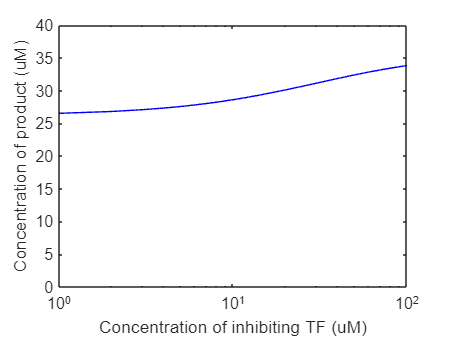

paramArray = 0:1:100;
g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    delta_m = 0.05;
    gamma_g = 0.02;
    delta_g = 0.01;
    
    gamma_g2 = 0.1;
    
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1
    
    I = 10; % EDIT FOR HW1
    C = paramArray(iParam); % ENDOGENOUS activatory transcription factor % EDIT FOR HW1
    
    M =@(C2,t) [-kon*(C+C2)-kon*I,  +koff*I,          koff     ,        0;
                +kon*I,             -koff*I-kon*(C+C2),             0,   +koff;
                +kon*(C+C2)      ,              0,   -koff-kon*I,   +koff;
                        0,          kon*(C+C2),         kon*I, -2*koff];
    
    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;
    
    f =@(p0,pr,pa,par,m,g,m2,C2) +gamma_m(p0,pr,pa,par)   - delta_m*m;
    g =@(p0,pr,pa,par,m,g,m2,C2) +gamma_g*m - delta_g*g;
    
    f2 =@(p0,pr,pa,par,m,g,m2,C2) + gamma_m(p0,pr,pa,par)   - delta_m*m2;
    g2 =@(p0,pr,pa,par,m,g,m2,C2) + gamma_g2*m2 - delta_g*C2;
    
    
    initialCondition = [1,0,0,0,0,0,0,0];
    
    dxdt = @(t,x)[M(x(8),t)*[x(1);x(2);x(3);x(4)];
        f(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
        g(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
        f2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
        g2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end

figure(17); clf;
semilogx(paramArray,g_storage, '-b')
xlabel('Concentration of inhibiting TF (uM)') % EDIT FOR HW1
ylabel('Concentration of product (uM)')
set(gca,'ylim', [0,40]);


half_max = mean([ max(g_storage), min(g_storage)]);
EC50 = interp1(g_storage,paramArray,half_max)

EC50 = 19.3293

# HW1 PART 2

Assume the concentration of activator is fixed at 10uM. 

Plot the steady-state amount of Protein as a function of the inhibitor concentration.

What is the concentration of inhibitor that results in half its maximal inhibition? This is called the IC50 of the inhibitor. 

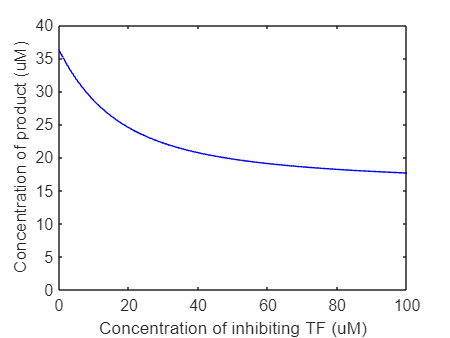

paramArray = 0:1:100;
g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    delta_m = 0.05;
    gamma_g = 0.02;
    delta_g = 0.01;
    
    gamma_g2 = 0.1;
    
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1
    
    I = paramArray(iParam); % EDIT FOR HW1
    C = 10; % ENDOGENOUS activatory transcription factor % EDIT FOR HW1
    
    M =@(C2,t) [-kon*(C+C2)-kon*I,  +koff*I,          koff     ,        0;
                +kon*I,             -koff*I-kon*(C+C2),             0,   +koff;
                +kon*(C+C2)      ,              0,   -koff-kon*I,   +koff;
                        0,          kon*(C+C2),         kon*I, -2*koff];
    
    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;
    
    f =@(p0,pr,pa,par,m,g,m2,C2) +gamma_m(p0,pr,pa,par)   - delta_m*m;
    g =@(p0,pr,pa,par,m,g,m2,C2) +gamma_g*m - delta_g*g;
    
    f2 =@(p0,pr,pa,par,m,g,m2,C2) + gamma_m(p0,pr,pa,par)   - delta_m*m2;
    g2 =@(p0,pr,pa,par,m,g,m2,C2) + gamma_g2*m2 - delta_g*C2;
    
    
    initialCondition = [1,0,0,0,0,0,0,0];
    
    dxdt = @(t,x)[M(x(8),t)*[x(1);x(2);x(3);x(4)];
        f(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
        g(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
        f2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
        g2(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end

figure(17); clf;
plot(paramArray,g_storage, '-b')
xlabel('Concentration of inhibiting TF (uM)') % EDIT FOR HW1
ylabel('Concentration of product (uM)')
set(gca,'ylim', [0,40]);


half_max = mean([ max(g_storage), min(g_storage)]);
IC50 = interp1(g_storage,paramArray,half_max)

IC50 = 13.3500